%小车倒立摆动力系统建模
%小车质量M,单摆质量m,单摆重心到关节距离l,单摆转动惯量I
%阻尼系数b,小车受力F,小车位置x,单摆与竖直向下方向角度θ
%P为单摆对关节作用力竖直方向分力,N为水平方向分力

对小车水平方向受力分析有:


$$M\ddot{x} =F-N-b\dot{x}$$


对单摆水平方向受力分析有:


$$N=m\;\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\left(x+\textrm{lsin}\theta \right)$$


也就是:


$$N=m\ddot{x} +\textrm{ml}\ddot{\theta \;} \cos \theta -\textrm{ml}{\dot{\theta} }^2 \sin \theta$$


对于单摆垂直方向受力分析有:


$$P=\textrm{mg}+m\;\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\left(\textrm{lcos}\theta \right)$$


也就是:


$$P=\textrm{mg}-\textrm{ml}\ddot{\theta} \;\sin \theta -m\;l\;\dot{\theta^2 } \cos \theta$$


对于关节力矩有如下力矩平衡方程:


$$-\textrm{Plsin}\theta -\textrm{Nlcos}\theta =I\ddot{\theta}$$


在工作点即θ≈0处局部线性化有:


$$\sin \theta \approx 0,\cos \theta \approx 1,\ddot{\theta} \approx 0$$


一般情况下我们希望系统平衡点在0附近,因此令:


$$\phi =\pi +\theta$$


则化简后有:


$$\left(I+{\textrm{ml}}^2 \right)\ddot{\phi} -\textrm{mgl}\phi =\textrm{ml}\ddot{x}$$



$$\left(M+m\right)\ddot{x} +b\dot{x} -\textrm{ml}\ddot{\phi} =F=u$$


对上两式进行拉普拉斯变换有:


$$\left(I+{\textrm{ml}}^2 \right)\Phi \left(s\right)s^2 -\textrm{mgl}\Phi \left(s\right)=\textrm{mlX}\left(s\right)s^2$$



$$\left(M+m\right)X\left(s\right)s^2 +\textrm{bX}\left(s\right)s-\textrm{ml}\Phi \left(s\right)s^2 =U\left(s\right)$$


则有单摆角度对输入的传递函数为:


$$G_{\textrm{pend}} \left(s\right)=\frac{\Phi \left(s\right)}{U\left(s\right)}=\frac{\textrm{mls}}{{\textrm{qs}}^3 +b\left(I+{\textrm{ml}}^2 \right)s^2 -\left(M+m\right)\textrm{mgls}-\textrm{bmgl}}$$


小车位置对输入的传递函数为:


$$G_{\textrm{car}} \left(s\right)=\frac{X\left(s\right)}{U\left(s\right)}=\frac{\left(I+{\textrm{ml}}^2 \right)s^2 -\textrm{mgl}}{{\textrm{qs}}^4 +b\left(I+{\textrm{ml}}^2 \right)s^3 -\left(M+m\right){\textrm{mgls}}^2 -\textrm{bmgls}}$$


其中:


$$q=\left(M+m\right)\left(I+{\textrm{ml}}^2 \right)-{\left(\textrm{ml}\right)}^2$$


得到传递函数之后输入MATLAB进行分析

%小车质量0.5kg 单摆质量0.2kg 阻尼系数0.1 
%单摆转动惯量0.018 重力加速度9.8 单摆长度0.6m
m_car = 0.5;
m_pend = 0.2; 
b = 0.1; 
I = 0.018;
g = 9.8;
L = 0.3;

q = (m_car + m_pend)*(I + m_pend*L^2)-(m_pend*L)^2;

s = tf('s');
%输入(小车受力F或者u)对小车位置传递函数
p_car = (((I + m_pend*L^2)/q)*s^2 - (m_pend*g*L/q))...
    /(s^4 + (b*(I +m_pend*L^2))*s^3/q - ((m_car + m_pend)*m_pend*g*L)*s^2/q - b*m_pend*g*L*s/q);
%输入对单摆对地角度传递函数
p_pend = (m_pend*L*s/q)...
    /(s^3 + (b*(I + m_pend*L^2))*s^2/q - ((m_car + m_pend)*m_pend*g*L)*s/q - b*m_pend*g*L/q);

sys_tf = [p_car; p_pend];
%设置输入为u也就是小车受力,输出为小车位置以及单摆角度
inputs = {'u'}; outputs = {'x'; 'phi'};
set(sys_tf, 'InputName', inputs,'OutputName', outputs);
sys_tf

sys_tf =
 
  From input "u" to output...
                       1.68e-05 s^2 - 0.0002743
   x:  ---------------------------------------------------------
       1.008e-05 s^4 + 1.68e-06 s^3 - 0.000192 s^2 - 2.743e-05 s
 
                              2.799e-05 s
   phi:  -----------------------------------------------------
         1.008e-05 s^3 + 1.68e-06 s^2 - 0.000192 s - 2.743e-05
 
Continuous-time transfer function.



%传递函数转换成状态空间描述
p = I*(m_car + m_pend) + m_car*m_pend*L^2;
A = [0        1                    0                        0;
     0  -(I+m_pend*L^2)*b/p  (m_pend^2*g*L^2)/p             0;
     0        0                    0                        1;
     0  -(m_pend*L*b)/p      m_pend*g*L*(m_car + m_pend)/p  0];
B = [0 (I + m_pend*L^2)/p 0 m_pend*L/p]';
C = [1 0 0 0; 0 0 1 0];
D = [0 0]';
%状态分别为:小车位置,小车加速度,单摆角度,单摆角速度
states = {'x' 'x_dot' 'phi' 'phi_dot'};
sys_ss = ss(A, B, C, D, 'statename', states, 'inputname', inputs, 'outputname', outputs)

sys_ss =
 
  A = 
                  x    x_dot      phi  phi_dot
   x              0        1        0        0
   x_dot          0  -0.1667    1.633        0
   phi            0        0        0        1
   phi_dot        0  -0.2778    19.06        0
 
  B = 
                u
   x            0
   x_dot    1.667
   phi          0
   phi_dot  2.778
 
  C = 
              x    x_dot      phi  phi_dot
   x          1        0        0        0
   phi        0        0        1        0
 
  D = 
        u
   x    0
   phi  0
 
Continuous-time state-space model.



%查看系统极点以及系统矩阵A的特征值
%可以看出系统不稳定,有右半平面极点,A的特征值有正实部
sys_poles = pole(sys_tf)

sys_poles =          0
    4.3538
   -4.3776
   -0.1428
    4.3538
   -4.3776
   -0.1428


sys_eigs = eig(A)

sys_eigs =          0
   -4.3776
   -0.1428
    4.3538


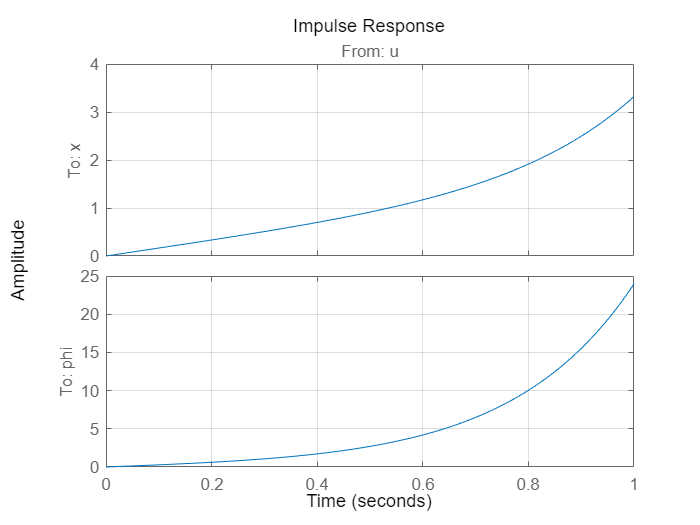

%查看开环系统单位脉冲响应,单位阶跃响应
%系统响应单调发散
impulse(sys_tf, 0 : 0.01 : 1);
grid on;

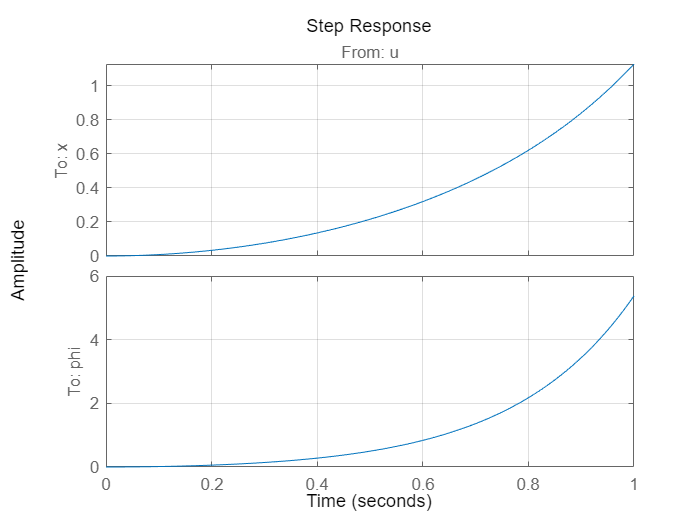

step(sys_tf, 0 : 0.01 : 1);
grid on;

%查看一下系统的能控性跟能观性
%可以看出系统是能控能观的,可以进行状态反馈控制
cb = ctrb(A, B);
r_cb = rank(cb)

r_cb = 4

ob = obsv(A, C);
r_ob = rank(ob)

r_ob = 4

%设计全维状态观测器
%全维观测器极点配置为:-20 -15 -25 -10
foe_p = [-20 -15 -25 -10];
L = place(A', C', foe_p);
L = L'

L =    34.6589   -4.9841
  279.9483  -84.8253
   -5.2688   35.1744
  -96.9965  309.6217


A_foe = A - L*C

A_foe =   -34.6589    1.0000    4.9841         0
 -279.9483   -0.1667   86.4586         0
    5.2688         0  -35.1744    1.0000
   96.9965   -0.2778 -290.5662         0


%检查一下观测器极点是否确实配置到指定位置
Afoe_eigs = eig(A_foe)

Afoe_eigs =   -10.0000
  -25.0000
  -15.0000
  -20.0000


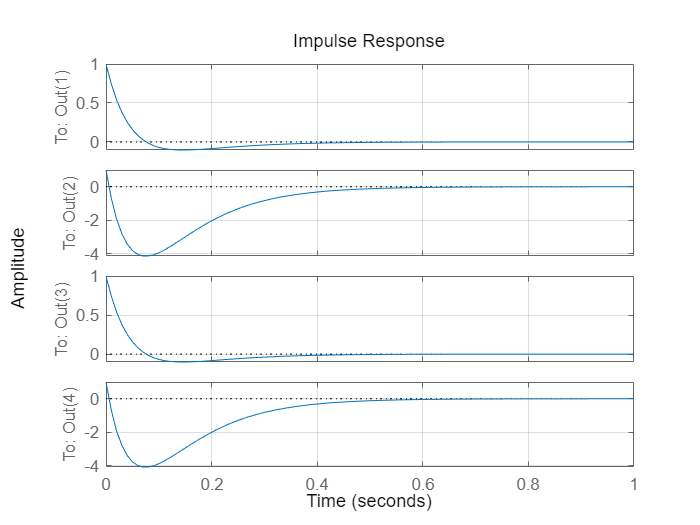

%将u跟y合并成一个列向量[u; y],则也需将B跟L按行合并成一个矩阵[B L]
B_foe = [B L];
%C为单位阵直接把状态向量输出
C_foe = eye(4);
D_foe = zeros(4,3);
sys_foe = ss(A_foe, ones(4,1), C_foe, zeros(4, 1));
%查看观测器误差输出脉冲响应,可以评估误差收敛速度,若不满足要求可调整观测器极点配置
impulse(sys_foe, 0 : 0.01 : 1);
grid on;

%设计降维观测器
%原系统中输出为位置x以及角度phi,因此选取R = [0 1 1 0; 1 0 0 1]构成非奇异矩阵P;
%设计一个二维的观测器并结合Q即可将系统状态观测到
R = [0 1 1 0; 1 0 0 1];
%step1 构造非奇异矩阵P
P = [C; R];
%step2 计算P逆并分块
Q = inv(P);
Q1 = Q( : , 1 : 2);
Q2 = Q( : , 3 : 4);
%step3 计算代数等价系统矩阵并分块
A_hat = P*A/P;
A11 = A_hat(1:2, 1:2);
A12 = A_hat(1:2, 3:4);
A21 = A_hat(3:4, 1:2);
A22 = A_hat(3:4, 3:4);
B_hat = P*B;
B1 = B_hat(1:2, : );
B2 = B_hat(3:4, : );
%step4 降维观测器极点配置为-15 -20,并综合出观测器反馈矩阵L_hat
roe_p = [-15 -20];
L_hat = place(A22', A12', roe_p);
L_hat = L_hat';
%step5 计算观测器系统矩阵,输入矩阵,输出矩阵,前馈矩阵
A_roe = A22 - L_hat*A12;
%检查一下观测器极点是否确实配置到指定位置
A_roe_eigs = eig(A_roe)

A_roe_eigs =    -20
   -15


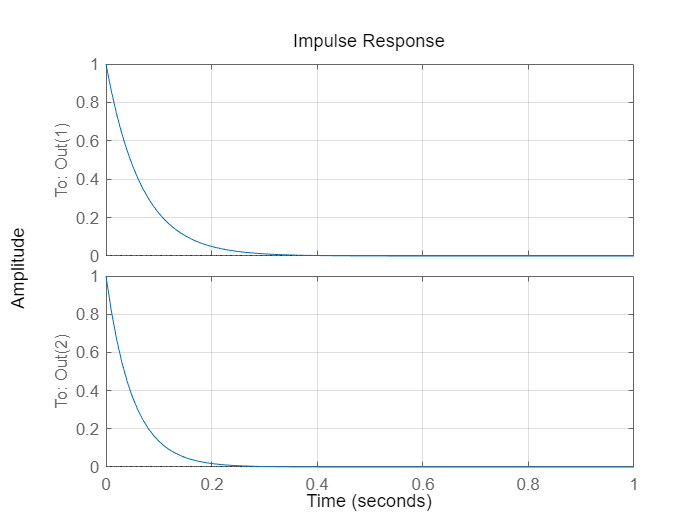

B_roe1 = A21 - L_hat*A11 + (A22 - L_hat*A12)*L_hat;
B_roe2 = B2 - L_hat*B1;
%此处将u与y合并成输入,因此将B也合并
B_roe = [B_roe2 B_roe1];
C_roe = eye(2);
D_roe = zeros(2, 3);
%定义Q1 + Q2*L_hat为最终状态输出中原输出y的系数y_coef
y_coef = Q1 + Q2*L_hat;
%最终观测器状态方程为:z_dot = A_roe*z + B_roe*[u;y];
%最终状态输出方程为x_hat = y_coe*y + Q2*z
sys_robv = ss(A_roe, ones(2, 1), eye(2), zeros(2, 1));
impulse(sys_robv, 0 : 0.01 : 1);
grid on;

%配置全状态反馈极点
p1 = -2 + 1i;
p2 = -2 - 1i;
p3 = -3 + 2i;
p4 = -3 - 2i;
%计算反馈矩阵K
K = place(A, B, [p1 p2 p3 p4])

K =    -2.3878   -3.1122   23.4127    5.4073


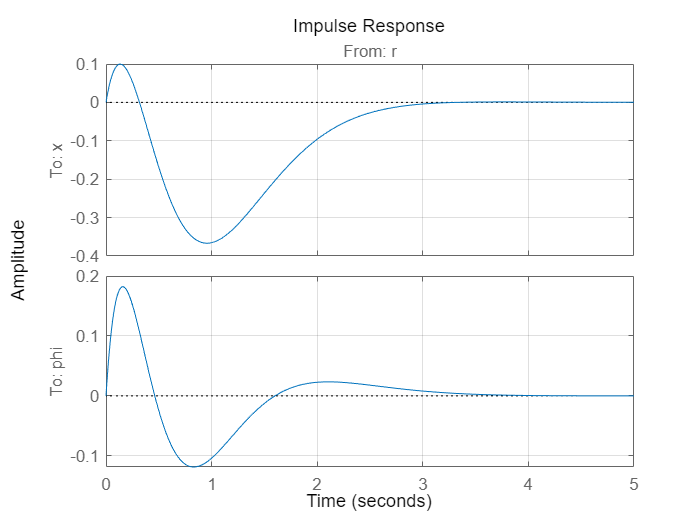

Ac = A - B*K;
Bc = B;
Cc = C;
Dc = D;
inputs_cl = {'r'};
%闭环状态空间描述
sys_cl = ss(Ac, Bc, Cc, Dc, 'StateName', states, 'InputName', inputs_cl, 'OutputName', outputs);
%查看闭环系统单位脉冲响应以及单位阶跃响应
impulse(sys_cl, 0 : 0.01 : 5);
grid on;

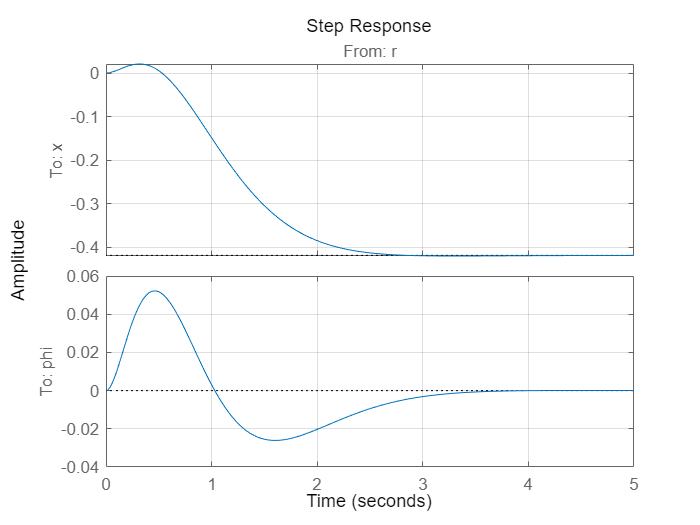

step(sys_cl, 0 : 0.01 : 5);
grid on;

%使用LQR配置极点
Q = C'*C;
Q(1, 1) = 10;
%我们希望单摆角度尽快降到0
Q(3, 3) = 1000;
%假定我们对输入不是很关心,即小车驱动电机输出力矩较大
R = 0.01;
K = lqr(A, B, Q, R);
Ac = A - B*K;
Bc = B;
Cc = C;
Dc = D;
sys_cl_lqr = ss(Ac, Bc, Cc, Dc, 'statename', states, 'inputname', inputs_cl, 'outputname', outputs)

sys_cl_lqr =
 
  A = 
                  x    x_dot      phi  phi_dot
   x              0        1        0        0
   x_dot       52.7    80.13   -606.8   -74.39
   phi            0        0        0        1
   phi_dot    87.84    133.6   -994.9     -124
 
  B = 
                r
   x            0
   x_dot    1.667
   phi          0
   phi_dot  2.778
 
  C = 
              x    x_dot      phi  phi_dot
   x          1        0        0        0
   phi        0        0        1        0
 
  D = 
        r
   x    0
   phi  0
 
Continuous-time state-space model.



%查看一下lqr综合出来的闭环极点
pole(sys_cl_lqr)

ans =  -21.2038 +20.7507i
 -21.2038 -20.7507i
  -0.7199 + 0.6780i
  -0.7199 - 0.6780i


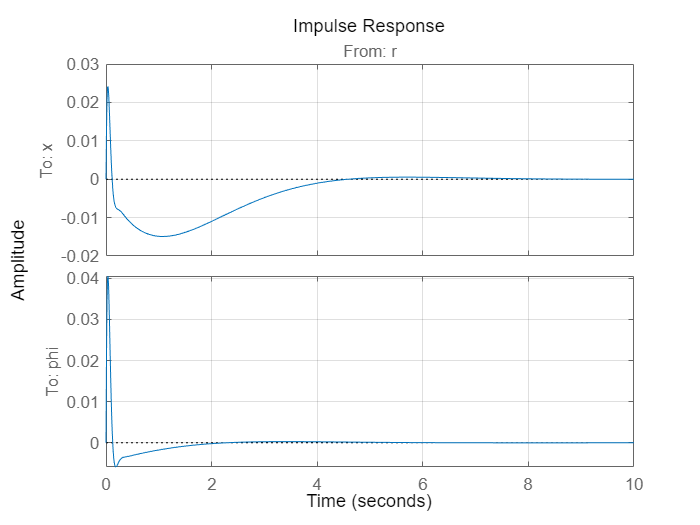

%查看使用lqr控制器的闭环系统单位脉冲响应以及单位阶跃响应
impulse(sys_cl_lqr, 0 : 0.01 : 10);
grid on;

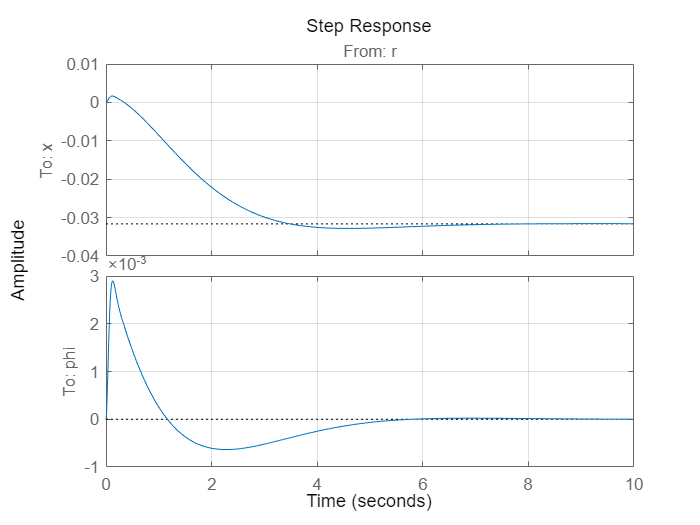

step(sys_cl_lqr, 0 : 0.01 : 10);
grid on;